clc; clear; close all;
% a
randn('seed',0);


N = [100 100];
x0 = [1;1];  

%next 100 data sets

m1 = [-5 0]';
s1 = [1 0;0 1];
X1 = mvnrnd(m1,s1,N(1))';
X2 = mvnrnd(m1,s1,N(1))';
%next 100 data sets

m1 = [5 0]';
s1 = [1 0;0 1];
X3 = mvnrnd(m1,s1,N(2))';
X4 = mvnrnd(m1,s1,N(2))';

FirstDataSet = [X1 x0 X3 x0]

FirstDataSet =    -3.8350   -4.3732   -4.9249   -4.6484   -5.6965   -3.3039   -4.9409   -3.2029   -4.7359   -4.1283   -6.4462   -5.7012   -3.7540   -5.6390   -4.4226   -5.3600   -5.1356   -6.3493   -6.2704   -4.0154   -5.0449   -5.7989   -5.7652   -4.1383   -5.0562   -4.4865   -4.6033   -4.2438   -4.5995   -6.3414   -4.6250   -3.8748   -4.2714   -7.3775   -5.2738   -5.3229   -4.6820   -5.5112   -5.0020   -3.3935   -4.1524   -4.7319   -5.9235   -5.0705   -4.8521   -5.5571   -5.3367   -4.5848   -3.4422   -7.4443
   -0.1274    0.5542   -1.0973   -0.7313    1.4047   -0.6202    0.2371   -1.5868   -0.4015   -0.7707   -0.2627    0.9765    0.9778    1.1700    0.1593    0.4995   -1.0554   -0.4507    1.2704    0.8987    0.4387   -1.2473    0.3247    0.3901   -0.4051    0.2923    2.5659   -0.4578   -1.6108   -2.6695   -0.7597   -0.6747   -1.1717    2.0329    0.9685    0.6703    0.4201   -2.8728    1.6859    0.0279   -0.9020   -2.0533    0.0891    2.0871    0.3651    0.8461   -0.1845    1.0307   -

SecondDataSet = [X2 x0 X4 x0]

SecondDataSet =    -5.7027   -4.6436   -4.3474   -4.7843   -5.2639   -3.1976   -5.6430   -4.8904   -5.7190   -4.5794   -6.9311   -4.3397   -6.1025   -5.1030   -6.0598   -6.2386   -6.8892   -5.9736   -4.7879   -4.5066   -3.4528   -4.3551   -7.1484   -6.0288   -5.1416   -7.5267   -5.3130   -5.5936   -4.6677   -4.4411   -4.1001   -5.2009   -5.2337   -3.5501   -3.1639   -5.3829   -4.8449   -5.9646   -4.9612   -4.2345   -5.5945   -4.8698   -4.9650   -5.6247   -5.5398   -3.1200   -6.0038   -5.4974   -6.5044   -5.0954
    0.4185    0.2473    0.7041    0.6319   -0.9924    1.7667   -0.3821   -0.9114   -0.9961    1.1951   -0.1594    2.7040   -0.1985   -0.1414    0.4113   -1.1791   -0.2778   -1.5811    1.0490    0.3027   -1.2265    0.0696   -0.3965    1.3888    1.3644    0.6582    0.4913    0.8007   -0.7673    0.3644   -0.3979    0.8643   -0.1776    1.8744    0.1724    1.2717   -0.0353   -1.5013    0.3654   -0.1987   -1.3897    0.2293    0.2712   -0.3664    1.3770   -0.7975   -0.9367   -0.0024   

% b
% perceptron algorith 
rho=0.05;           % Learning rate

w_ini = [1 1]';
N = [101 101];
y1=[-ones(1,N(1)) ones(1,N(2))];
[w_perceptron_FirstDataSet,iter,mis_clas]=perce(FirstDataSet,y1,w_ini,rho)

w_perceptron_FirstDataSet =     1.2656
   -1.2612


iter = 20000

mis_clas = 1

[w_perceptron_SecondDataSet,iter,mis_clas]=perce(SecondDataSet,y1,w_ini,rho)

w_perceptron_SecondDataSet =     1.2457
   -1.2441


iter = 20000

mis_clas = 1

%sum of error squares classifier
w_SSErr_FirstDataSet = inv(FirstDataSet*FirstDataSet')*(FirstDataSet*y1')

w_SSErr_FirstDataSet =     0.1928
   -0.0013


w_SSErr_SecondDataSet = inv(SecondDataSet*SecondDataSet')*(SecondDataSet*y1')

w_SSErr_SecondDataSet =     0.1932
   -0.0198




%LMS algorithm
w_LMS_FirstDataSet =LMSalg(FirstDataSet,y1,w_ini)

w_LMS_FirstDataSet =     0.1976
    0.5428


w_LMS_SecondDataSet =LMSalg(SecondDataSet,y1,w_ini)

w_LMS_SecondDataSet =     0.1942
    0.6760


%c
f1 = @() perce(FirstDataSet,y1,w_ini,rho);
f2 = @() perce(SecondDataSet,y1,w_ini,rho);
f3=  @() inv(FirstDataSet*FirstDataSet')*(FirstDataSet*y1');
f4=  @() inv(SecondDataSet*SecondDataSet')*(SecondDataSet*y1');
f5 = @() LMSalg(FirstDataSet,y1,w_ini);
f6 = @() LMSalg(SecondDataSet,y1,w_ini);
performance_perceptron_FrstDataSet = timeit(f1)

performance_perceptron_FrstDataSet = 0.4511

performance_perceptron_SecondDataSet = timeit(f2)

performance_perceptron_SecondDataSet = 0.4387

performance_SSErr_FrstDataSet = timeit(f3)

performance_SSErr_FrstDataSet = 7.3192e-06

performance_SSErr_SecondDataSet = timeit(f4)

performance_SSErr_SecondDataSet = 7.0301e-06

performance_LMS_FirstDataSet = timeit(f5)

performance_LMS_FirstDataSet = 9.6119e-05

performance_LMS_SecondDataSet = timeit(f6)

performance_LMS_SecondDataSet = 5.2525e-05

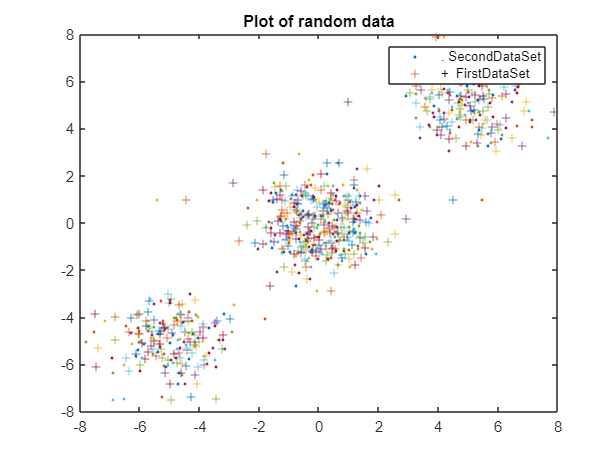

%d
i = 1;
while i < 202
figure(1), plot(FirstDataSet(:,i),FirstDataSet(:,i+1),'+')
plot(SecondDataSet(:,i),FirstDataSet(:,i+1),'.')
i=i+1;
hold on
end
title("Plot of random data")
legend(". SecondDataSet", "+  FirstDataSet")

 
bou = [1.5 1; 0.2 -1];
resolu = (bou(2)-bou(1))/100;
plot_NN_reg(w_perceptron_FirstDataSet,bou,resolu,figure(1))

Error using plot_NN_reg (line 34)
'model' parameter must be a character vector


matlab:matlab.internal.addons.launchers.showExplorer('ErrorRecovery', 'identifier', 'RL', 'focused', 'sim');